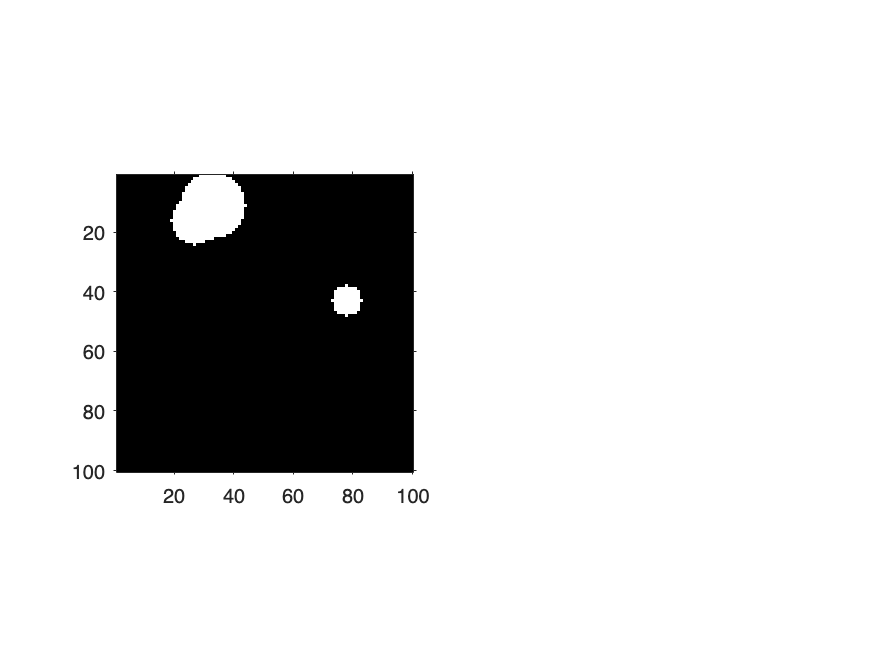

clear all; close all;
% Parameters
imageSize = [100, 100];  % Size of the binary image
numCircles = 3;         % Number of circles to generate
minRadius = 5;          % Minimum radius of circles
maxRadius = 15;          % Maximum radius of circles

% Initialize binary image
binaryImage = false(imageSize);

% Generate random circles
for i = 1:numCircles
    % Generate random center coordinates
    centerX = randi(imageSize(2));
    centerY = randi(imageSize(1));
    
    % Generate random radius
    radius = randi([minRadius, maxRadius]);
    
    % Generate circle
    [columnsInImage, rowsInImage] = meshgrid(1:imageSize(2), 1:imageSize(1));
    circlePixels = (rowsInImage - centerY).^2 + (columnsInImage - centerX).^2 <= radius.^2;
    
    % Add circle to binary image
    binaryImage = binaryImage | circlePixels;
end

% Display binary image
%imshow(binaryImage);
C = binaryImage;
figure ();
subplot(1,2,1);
imshow(C);

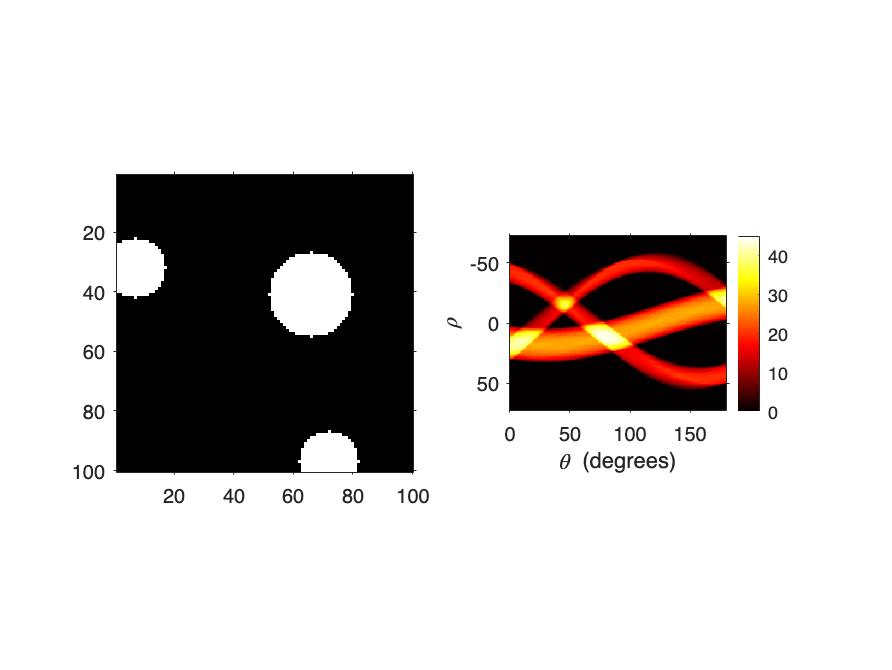

%{
%% Make a circle
x = linspace(-1,1, 100); y = x;
[X,Y] = meshgrid(x,y);
R = sqrt(X.^2 + Y.^2);
C = zeros(size(X));
C = R < 0.5;
figure ();
subplot(1,2,1);
imshow(C);
%% Make a rectangle
%C = zeros(size(X));
%C(20:80,40:60)=1.0;
%subplot(1,2,2);
%imshow(C);
%}

%% Compute Radon Transform
theta = 0:180;
[R,p] = radon(C,theta);

%Display sinogram

subplot(1,2,2);
iptsetpref('ImshowAxesVisible','on')
imshow(R,[],'Xdata',theta,'Ydata',p,'InitialMagnification','fit')
xlabel('\theta (degrees)')
ylabel('\rho')
colormap(gca,hot), colorbar

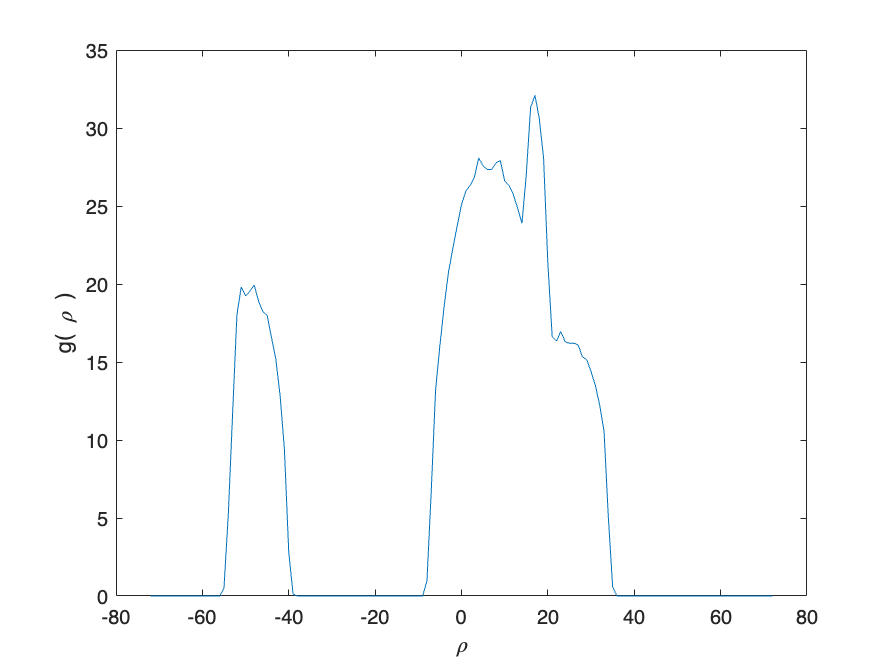


%% plot cross section
figure();
plot(p,R(:,100));xlabel('\rho');ylabel('g( \rho )');

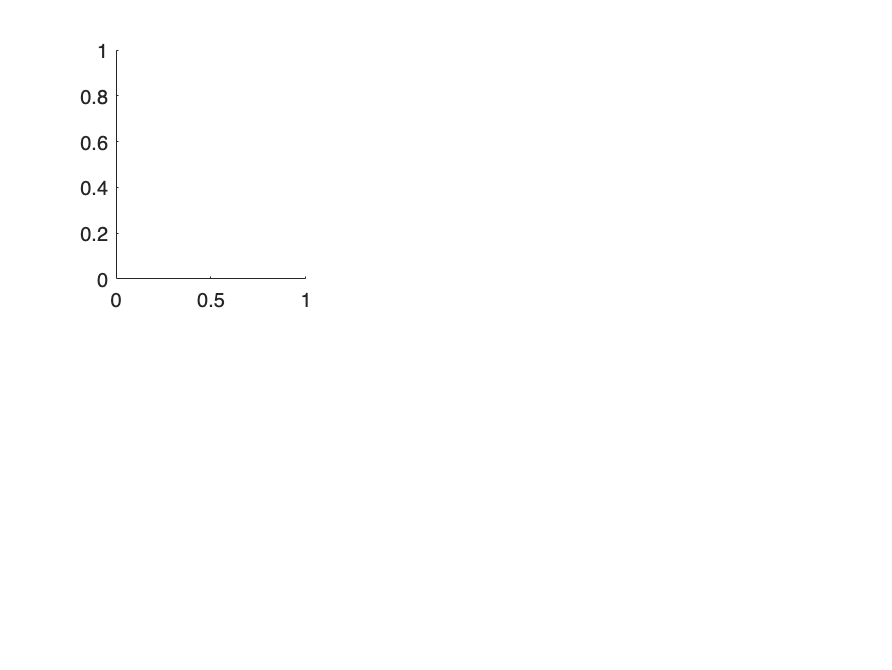


%% Recover image

figure();

subplot(231); 

Cp = iradon(R,theta,"linear","Ram-Lak");
psnr_ =psnr(Cp,double(C));

Error using psnr>checkImages
A and REF must have the same size.

Error in psnr (line 69)
checkImages(A,ref);

imagesc(Cp); colormap("gray"); 
title({['filter = Ram-Lak'] ...
    ['psnr = ', num2str(psnr_)]}); axis equal
ylim([0 100]);

subplot(232); 
Cp = iradon(R,theta,"linear","Shepp-Logan");
imagesc(Cp); colormap("gray"); 
title({['filter = Shepp-Logan'] ...
    ['psnr = ', num2str(psnr_)]}); axis equal
ylim([0 100]);

subplot(233); 
Cp = iradon(R,theta,"linear","Cosine");
imagesc(Cp); colormap("gray"); 
title({['filter = Cosine'] ...
    ['psnr = ', num2str(psnr_)]}); axis equal
ylim([0 100]);

subplot(234); 
Cp = iradon(R,theta,"linear","Hamming");
imagesc(Cp); colormap("gray"); 
title({['filter = Hamming'] ...
    ['psnr = ', num2str(psnr_)]}); axis equal
ylim([0 100]);

subplot(235); 
Cp = iradon(R,theta,"linear","Hann");
imagesc(Cp); colormap("gray"); 
title({['filter = Hann'] ...
    ['psnr = ', num2str(psnr_)]}); axis equal
ylim([0 100]);

subplot(236); 
Cp = iradon(R,theta,"linear","None");
imagesc(Cp); colormap("gray"); 
title({['filter = None'] ...
    ['psnr = ', num2str(psnr_)]}); axis equal
ylim([0 100]);